# nb20230712_094600_sharptrack2paxinos_sagittal_probe.mlx

## 0 Place a mark at the optic fiber tip

addpath('\\ettina\Magill_Lab\Kouichi Nakamura\Analysis\allenCCFdata')
cd('\\ettina\Magill_Lab\Kouichi Nakamura\Analysis\Images from Otto\20230406 kms058') %TODO

subject_id = 'Paxinos_sagittal' %TODO

subject_id = 'Paxinos_sagittal'


% * remember to run one cell at a time, instead of the whole script at once *

% directory of histology images
image_folder = '\\ettina\Magill_Lab\Kouichi Nakamura\Analysis\Images from Otto\20230406 kms058\Paxinos sagittal probe';  %TODO


% directory to save the processed images -- can be the same as the above image_folder
% results will be put inside a new folder called 'processed' inside of this image_folder
save_folder = image_folder;

% name of images, in order anterior to posterior or vice versa
% once these are downsampled they will be named ['original name' '_processed.tif']
image_file_names = dirregexp(image_folder, '.+\_dots\.tif$'); % get the contents of the image_folder
image_file_names = natsortfiles({image_file_names.name});


disp(image_file_names')

    {'2023-07-11 11 40 59_dots.tif'}


% image_file_names = {'slide no 2_RGB.tif','slide no 3_RGB.tif','slide no 4_RGB.tif'}; % alternatively, list each image in order

% if the images are individual slices (as opposed to images of multiple
% slices, which must be cropped using the cell CROP AND SAVE SLICES)
image_files_are_individual_slices = true;

% use images that are already at reference atlas resolution (here, 10um/pixel)
use_already_downsampled_image = false; %TODO

% pixel size parameters: microns_per_pixel of large images in the image
% folder (if use_already_downsampled_images is set to false);
% microns_per_pixel_after_downsampling should typically be set to 10 to match the atlas
microns_per_pixel = 6.86 ; %TODO 
microns_per_pixel_after_downsampling = 10 ;%TODO



% ----------------------
% additional parameters
% ----------------------

% if the images are cropped (image_file_are_individual_slices = false),
% name to save cropped slices as; e.g. the third cropped slice from the 2nd
% image containing many slices will be saved as: save_folder/processed/save_file_name02_003.tif
save_file_name = [subject_id,'_'];

% increase gain if for some reason the images are not bright enough
gain = 1; 

% plane to view ('coronal', 'sagittal', 'transverse')
plane = 'sagittal'; %TODO

% size in pixels of reference atlas brain. For coronal slice, this is 800 x 1140
if strcmp(plane,'coronal')
    atlas_reference_size = [800 1140]; 
elseif strcmp(plane,'sagittal')
    atlas_reference_size = [800 1320]; 
elseif strcmp(plane,'transverse')
    atlas_reference_size = [1140 1320];
end






% finds or creates a folder location for processed images -- 
% a folder within save_folder called processed
folder_processed_images = fullfile(save_folder, 'processed');
if ~exist(folder_processed_images)
    mkdir(folder_processed_images)
end


% directory of histology
processed_images_folder = folder_processed_images; %TODO

% name the saved probe points, to avoid overwriting another set of probes going in the same folder
probe_save_name_suffix = '_paxinos'; %TODO

% directory of reference atlas files
annotation_volume_location = "\\ettina\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\annotation_volume_10um_by_index.npy";
structure_tree_location = "\\ettina\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\structure_tree_safe_2017.csv";
template_volume_location = "\\ettina\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\template_volume_10um.npy";

% plane to view ('coronal', 'sagittal', 'transverse')
% plane = 'sagittal';


% load the reference brain and region annotations
if ~exist('av','var') || ~exist('st','var') || ~exist('tv','var')
    disp('loading reference atlas...')
    av = readNPY(annotation_volume_location);
    st = loadStructureTree(structure_tree_location);
    tv = readNPY(template_volume_location);
end

loading reference atlas...



% select the plane for the viewer
if strcmp(plane,'coronal')
    av_plot = av;
    tv_plot = tv;
elseif strcmp(plane,'sagittal')
    av_plot = permute(av,[3 2 1]);
    tv_plot = permute(tv,[3 2 1]);
elseif strcmp(plane,'transverse')
    av_plot = permute(av,[2 3 1]);
    tv_plot = permute(tv,[2 3 1]);
end

## 1. ENTER PARAMETERS AND FILE LOCATION

% subject_id = 'kms058' %TODO

% file location of object points
% save_folder = '\\ettin\Magill_Lab\Kouichi Nakamura\Analysis\Images from Otto\20230406 kms058\RGB2\processed'


% directory of reference atlas files
% annotation_volume_location = "\\ettin\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\annotation_volume_10um_by_index.npy";
% structure_tree_location = "\\ettin\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\structure_tree_safe_2017.csv";

% name of the saved object points
object_save_name_suffix = probe_save_name_suffix;% [subject_id,'_opticfiber_'];

% either set to 'all' or a list of indices from the clicked objects in this file, e.g. [2,3]
objects_to_analyze = 'all';

% plane used to view when points were clicked ('coronal' -- most common, 'sagittal', 'transverse')
% plane = 'sagittal';

% brain figure black or white
black_brain = true;


## 2. LOAD THE REFERENCE ANNOTATIONS AND PROBE POINTS


% load the reference brain annotations
if ~exist('av','var') || ~exist('st','var')
    disp('loading reference atlas...')
    av = readNPY(annotation_volume_location);
    st = loadStructureTree(structure_tree_location);
end


% load object points
objectPoints = load(fullfile(save_folder, 'processed',['probe_points' object_save_name_suffix]));

% determine which objects to analyze
if strcmp(objects_to_analyze,'all')
    objects = 1:size(objectPoints.pointList.pointList,1);
else
    objects = objects_to_analyze;
end 

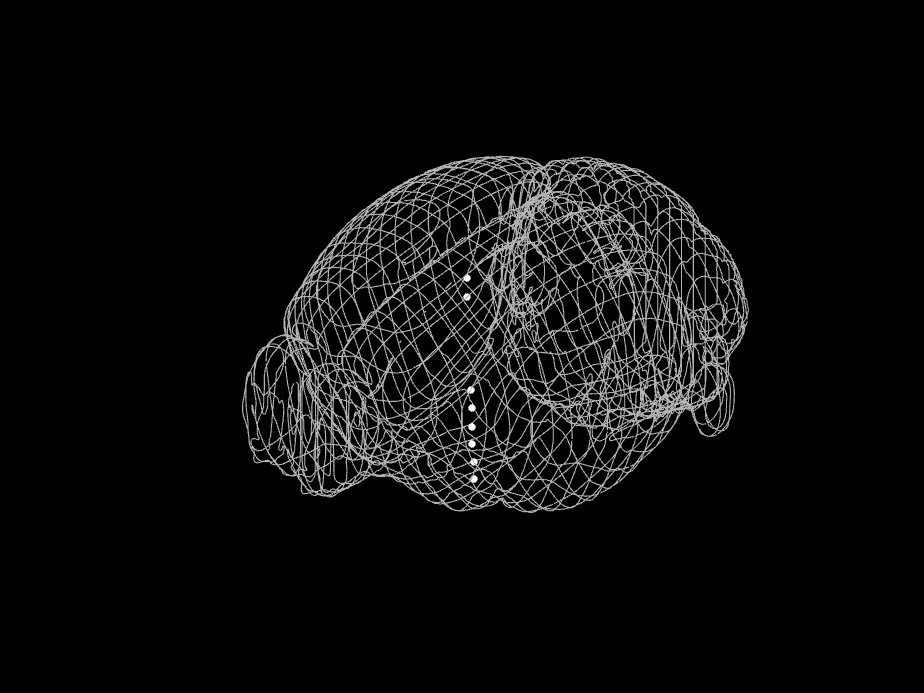

Clicked points for object 1


                  name                   acronym      AP_location    DV_location    ML_location    avIndex
    ________________________________    __________    ___________    ___________    ___________    _______
    {'Primary motor area Layer 2/3'}    {'MOp2/3'}        0.23          1.02           -1.41       {[ 21]}
    {'Primary motor area Layer 5'  }    {'MOp5'  }        0.22           1.6           -1.41       {[ 22]}
    {'Caudoputamen'                }    {'CP'    }        0.08           4.4           -1.41       {[574]}
    {'Caudoputamen'                }    {'CP'    }        0.06          4.94           -1.41       {[574]}
    {'Pallidum'                    }    {'PAL'   }        0.05          5.49           -1.41       {[609]}
    {'Substantia innominata'       }    {'SI'  

%% BRING UP THE RELEVANT DATA FOR EACH PROBE POINTS, FOR FURTHER ANALYSIS

% initialize cell array containing info on each clicked point
if length(objects) > 1
    roi_annotation = cell(length(objects),1);
    roi_location = cell(length(objects),1);
end

% generate needed values
bregma = allenCCFbregma(); % bregma position in reference data space
atlas_resolution = 0.010; % mm

% plot brain grid
ProbeColors = [1 1 1; 1 .75 0;  .3 1 1; .4 .6 .2; 1 .35 .65; .7 .7 1; .65 .4 .25; .7 .95 .3; .7 0 0; .6 0 .7; 1 .6 0]; 
% order of colors: {'white','gold','turquoise','fern','bubble gum','overcast sky','rawhide', 'green apple','purple','orange','red'};
fwireframe = plotBrainGrid([], [], [], black_brain); hold on; 
fwireframe.InvertHardcopy = 'off';



for object_num = objects
    
    selected_object = objects(object_num);
        
    % get the object points for the currently analyzed object    
    if strcmp(plane,'coronal')
        curr_objectPoints = objectPoints.pointList.pointList{selected_object,1}(:, [3 2 1]);
    elseif strcmp(plane,'sagittal')
        curr_objectPoints = objectPoints.pointList.pointList{selected_object,1}(:, [1 2 3]);
    elseif strcmp(plane,'transverse')
        curr_objectPoints = objectPoints.pointList.pointList{selected_object,1}(:, [1 3 2]);
    end

    % plot points on the wire frame brain
    figure(fwireframe); hold on
    hp = plot3(curr_objectPoints(:,1), curr_objectPoints(:,3), curr_objectPoints(:,2), '.','linewidth',2, 'color',[ProbeColors(object_num,:) .2],'markers',10);   

    % use the point's position in the atlas to get the AP, DV, and ML coordinates
    ap = -(curr_objectPoints(:,1)-bregma(1))*atlas_resolution;
    dv = (curr_objectPoints(:,2)-bregma(2))*atlas_resolution;
    ml = (curr_objectPoints(:,3)-bregma(3))*atlas_resolution;

    roi_location_curr = [ap dv ml];
    
    % initialize array of region annotations
    roi_annotation_curr = cell(size(curr_objectPoints,1),3);    
    
    % loop through every point to get ROI locations and region annotations
    for point = 1:size(curr_objectPoints,1)

        % find the annotation, name, and acronym of the current ROI pixel
        ann = av(curr_objectPoints(point,1),curr_objectPoints(point,2),curr_objectPoints(point,3));
        name = st.safe_name{ann};
        acr = st.acronym{ann};

        roi_annotation_curr{point,1} = ann;
        roi_annotation_curr{point,2} = name;
        roi_annotation_curr{point,3} = acr;

    end
    
    % save results in cell array
    if length(objects) > 1
        roi_annotation{object_num} = roi_annotation_curr;
        roi_location{object_num} = roi_location_curr;
    else
        roi_annotation = roi_annotation_curr;
        roi_location = roi_location_curr;
    end
 
    % display results in a table
    disp(['Clicked points for object ' num2str(selected_object)])
    roi_table = table(roi_annotation_curr(:,2),roi_annotation_curr(:,3), ...
                        roi_location_curr(:,1),roi_location_curr(:,2),roi_location_curr(:,3), roi_annotation_curr(:,1), ...
         'VariableNames', {'name', 'acronym', 'AP_location', 'DV_location', 'ML_location', 'avIndex'});
     disp(roi_table)
    
end



% now, use roi_location and roi_annotation for your further analyses

## Prepare coordinates from Paxinos

vns = { 'VariableNames', {'AP_location','DV_location','ML_location', 'figure'}};


mat_PaFr = [...
    0, 0, 1.32, 112;...
    0, 0.5, 1.32, 112;...
    0, 3, 1.32, 112;...
    0, 3.5, 1.32, 112;...
    0, 4, 1.32, 112;...
    0, 4.5, 1.32, 112;...
    0, 5, 1.32, 112;...
    0, 5.5, 1.32, 112;...
    ]

mat_PaFr =          0         0    1.3200  112.0000
         0    0.5000    1.3200  112.0000
         0    3.0000    1.3200  112.0000
         0    3.5000    1.3200  112.0000
         0    4.0000    1.3200  112.0000
         0    4.5000    1.3200  112.0000
         0    5.0000    1.3200  112.0000
         0    5.5000    1.3200  112.0000



PaFr = array2table(mat_PaFr, vns{:});

PaFr.AP_location = PaFr.AP_location * -1;


## DV

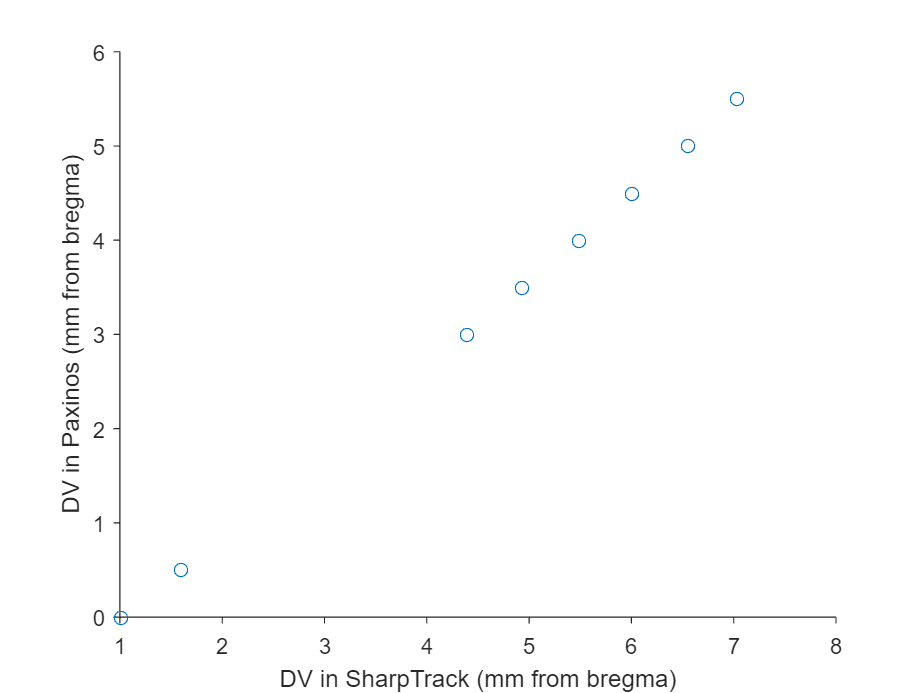

figure
ax = axes;
plot(roi_table.DV_location, PaFr.DV_location, 'o')
box off;
tickdir out;
xlabel('DV in SharpTrack (mm from bregma)')
ylabel('DV in Paxinos (mm from bregma)')


X = [ones(size(roi_table.DV_location)) , roi_table.DV_location];
Y = PaFr.DV_location;
b_DV = X\Y

b_DV =    -0.9575
    0.9082


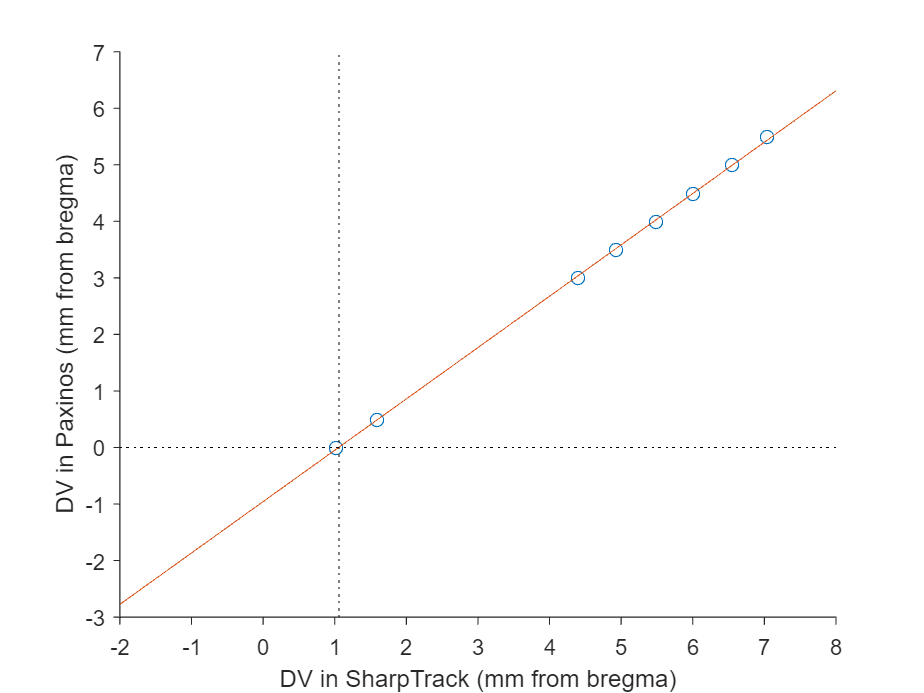


x = -2:0.01:8; % 10 micron
y = b_DV(1) + b_DV(2) * x;

hold on
ax.XTick = -2:8;
plot(x, y);
plot(xlim, [0 0], 'k:')
plot([x(find(y >=0,1,"first")), x(find(y >=0,1,"first"))], ylim, 'k:')

fprintf("At y = 0, i.e. the real bregma, SharpTrack DV value is %.3f mm\n", x(find(y >=0,1,"first")));

At y = 0, i.e. the real bregma, SharpTrack DV value is 1.060 mm


fprintf("SharpTrack depth x can be converted to Paxinos depth by y = %.3f * x %+.3f\n", b_DV(2), b_DV(1));

SharpTrack depth x can be converted to Paxinos depth by y = 0.908 * x -0.957


## `8. `Display Probe Track

Probe2 was patricularly bad

Using OMERO and trigonometry, I estimated that distance from the surface to the tip on the tissue secion

eg.

`sqrt(200^2 + 4251^2)`

travel across 4 * 50 µm sections to reach the surface

4251 µm in one section

Looking at probe 4, shrinkiage was 15%

Lab note depth and depth in images are up to 28% different.



%% ENTER PARAMETERS AND FILE LOCATION

% file location of probe points
% processed_images_folder = 'C:\Drive\Histology\brainX\processed';

% directory of reference atlas files
% annotation_volume_location = 'C:\Drive\Histology\for tutorial\annotation_volume_10um_by_index.npy';
% structure_tree_location = 'C:\Drive\Histology\for tutorial\structure_tree_safe_2017.csv';

% name of the saved probe points
% probe_save_name_suffix = 'electrode_track_1';
% probe_save_name_suffix = '';

% either set to 'all' or a list of indices from the clicked probes in this file, e.g. [2,3]
probes_to_analyze = 'all';  % [1 2]

% --------------
% key parameters
% --------------
% how far into the brain did you go from the surface, either for each probe or just one number for all -- in mm

% from recording notes:
probe_lengths = [...
    5.6, ... 
    ]

probe_lengths = 5.6000


% measured on slides
% probe_lengths = [...
%     1.9000, ... 
%     4.2557, ... (**77%** of 5.5060) Note was wrong???
%     4.323, ... (85% of 5.0943)
%     3.885,... 5.4270, ...
%     4.3065, ... (92% of 4.6550) tissue image
%     5.3120, ...
%     5.0493, ...
%     5.3120, ...
%     4.3810, ...
%     ]

% from the bottom tip, how much of the probe contained recording sites -- in mm
active_probe_length = 3.84;

% distance queried for confidence metric -- in um
probe_radius = 32; 

% overlay the distance between parent regions in gray (this takes a while)
show_parent_category = false; 

% plot this far or to the bottom of the brain, whichever is shorter -- in mm
distance_past_tip_to_plot = .5;

% set scaling e.g. based on lining up the ephys with the atlas
% set to *false* to get scaling automatically from the clicked points
scaling_factor = false;


% ---------------------
% additional parameters
% ---------------------
% plane used to view when points were clicked ('coronal' -- most common, 'sagittal', 'transverse')
% plane = 'coronal';

% probe insertion direction 'down' (i.e. from the dorsal surface, downward -- most common!) 
% or 'up' (from a ventral surface, upward)
probe_insertion_direction = 'down';

% show a table of regions that the probe goes through, in the console
show_region_table = true;
      
% black brain?
black_brain = true;


% close all



### 9. GET AND PLOT PROBE VECTOR IN ATLAS SPACE


% load the reference brain annotations
if ~exist('av','var') || ~exist('st','var')
    disp('loading reference atlas...')
    av = readNPY(annotation_volume_location);
    st = loadStructureTree(structure_tree_location);
end

% select the plane for the viewer
if strcmp(plane,'coronal')
    av_plot = av;
elseif strcmp(plane,'sagittal')
    av_plot = permute(av,[3 2 1]);
elseif strcmp(plane,'transverse')
    av_plot = permute(av,[2 3 1]);
end

% load probe points
probePoints = load(fullfile(processed_images_folder, ['probe_points' probe_save_name_suffix]));
ProbeColors = .75*[1.3 1.3 1.3; 1 .75 0;  .3 1 1; .4 .6 .2; 1 .35 .65; .7 .7 .9; .65 .4 .25; .7 .95 .3; .7 0 0; .6 0 .7; 1 .6 0]; 
% order of colors: {'white','gold','turquoise','fern','bubble gum','overcast sky','rawhide', 'green apple','red','purple','orange'};
fwireframe = [];

% % scale active_probe_length appropriately
% active_probe_length = active_probe_length*100;

% determine which probes to analyze
if strcmp(probes_to_analyze,'all')
    probes = 1:size(probePoints.pointList.pointList,1);
else
    probes = probes_to_analyze;
end 



% initialize cell array containing info on each clicked point
if length(probes) > 1
    roi_annotation = cell(length(probes),1);
    roi_location = cell(length(probes),1);
end

% generate needed values
bregma = allenCCFbregma(); % bregma position in reference data space
atlas_resolution = 0.010; % mm

### 10. PLOT EACH PROBE -- FIRST FIND ITS TRAJECTORY IN REFERENCE SPACE

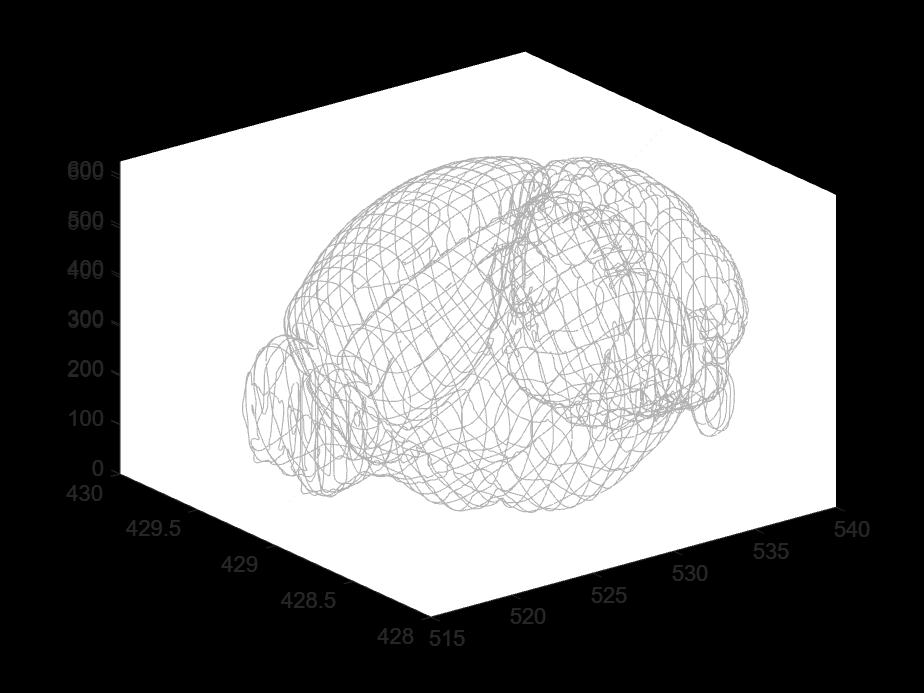


% create a new figure with wireframe
fwireframe = plotBrainGrid([], [], fwireframe, black_brain);
hold on; 
fwireframe.InvertHardcopy = 'off';

fwireframe2 = plotBrainGrid([], [], fwireframe, black_brain);

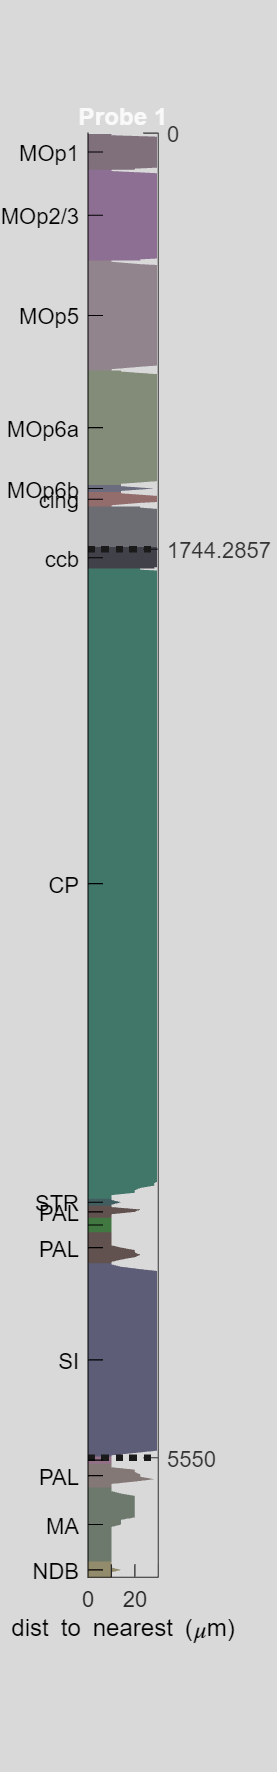

hold on; 

fwireframe2.InvertHardcopy = 'off';

fig_probes = gobjects(1,length(probes));
borders_table = cell(1,length(probes)) %TODO

borders_table = 1×1 cell array
    {0×0 double}

T_probes = table(repmat(string(subject_id), size(probes')),...
    strings(length(probes),1), ...
    probes',...
    strings(length(probes),1), ...
    probe_lengths' * 1000,... in um
    NaN(size(probes')),...
    NaN(size(probes')),...
    NaN(size(probes')),...
    NaN(size(probes')),...
    NaN(size(probes')),...
    strings(length(probes),1), ...    
    'VariableNames',{'subject_id','session_id','probe_id','probe_AB',...
        'depth_record_um','depth_from_anatomy_um','scaling', ...
        'scaling2',...
        'tip_active_um', 'top_active_um', 'probe_note'}) %TODO

T_probes = 1×11 table
        subject_id        session_id    probe_id    probe_AB    depth_record_um    depth_from_anatomy_um    scaling    scaling2    tip_active_um    top_active_um    probe_note
    __________________    __________    ________    ________    _______________    _____________________    _______    ________    _____________    _____________    __________
    "Paxinos_sagittal"        ""           1           ""            5600                   NaN               NaN        NaN            NaN              NaN             ""    

getting probe scaling from histology data...


probe length of 6.2393 mm in reference atlas space compared to a reported 5.6 mm


probe scaling of 1.1142
 


probe length of 5.7389 mm in reference atlas space compared to a reported 5.6 mm


probe scaling of 1.0248
 


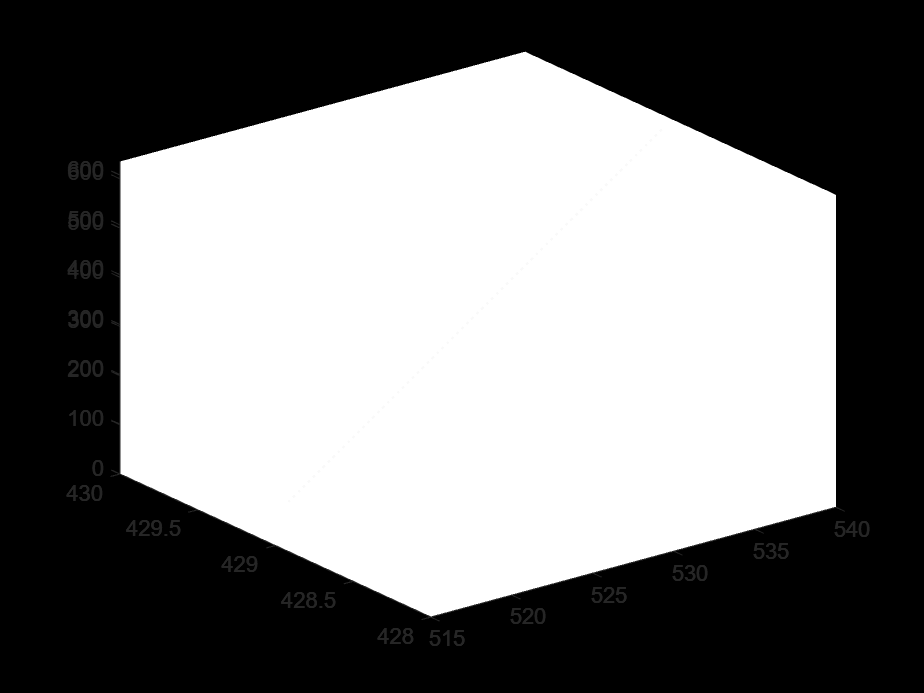

borders_table = 18×5 table
    upperBorder    lowerBorder     acronym                      name                     avIndex
    ___________    ___________    __________    _____________________________________    _______
          0            150        {'MOp1'  }    {'Primary motor area Layer 1'       }       20  
        150            530        {'MOp2/3'}    {'Primary motor area Layer 2/3'     }       21  
        530            990        {'MOp5'  }    {'Primary motor area Layer 5'       }       22  
        990           1470        {'MOp6a' }    {'Primary motor area Layer 6a'      }       23  
       1470           1500        {'MOp6b' }    {'Primary motor area Layer 6b'      }       24  
       1500           1560        {'cing'  }    {'cingulum bundle'                  }     1244  
       1560           1730 


c_Tapdvml_contacts = cell(length(probes),1);

for selected_probe = probes

    % get the probe points for the currently analyzed probe
    if strcmp(plane,'coronal')
        curr_probePoints = probePoints.pointList.pointList{selected_probe,1}(:, [3 2 1]);
    elseif strcmp(plane,'sagittal')
        curr_probePoints = probePoints.pointList.pointList{selected_probe,1}(:, [1 2 3]);    elseif strcmp(plane,'transverse')
        curr_probePoints = probePoints.pointList.pointList{selected_probe,1}(:, [1 3 2]);
    end



    % get user-defined probe length from experiment
    if length(probe_lengths) > 1
        probe_length = probe_lengths(selected_probe);
    else
        probe_length = probe_lengths;
    end

    % get the scaling-factor method to use
    if scaling_factor
        use_tip_to_get_reference_probe_length = false;
        reference_probe_length = probe_length * scaling_factor;
        disp(['probe scaling of ' num2str(scaling_factor) ' determined by user input']);
    else
        use_tip_to_get_reference_probe_length = true;
        disp(['getting probe scaling from histology data...']);
    end

    % get line of best fit through points
    % m is the mean value of each dimension; p is the eigenvector for largest eigenvalue
    [m,p,s] = best_fit_line(curr_probePoints(:,1), curr_probePoints(:,2), curr_probePoints(:,3));
    if isnan(m(1))
        disp(['no points found for probe ' num2str(selected_probe)])
        continue
    end

    % ensure proper orientation: want 0 at the top of the brain and positive distance goes down into the brain
    if p(2)<0
        p = -p;
    end

    % determine "origin" at top of brain -- step upwards along tract direction until tip of brain / past cortex
    ann = 10;
    out_of_brain = false;
    while ~(ann==1 && out_of_brain) % && distance_stepped > .5*active_probe_length)
        m = m-p; % step 10um, backwards up the track
        ann = av(round(m(1)),round(m(2)),round(m(3))); %until hitting the top
        if strcmp(st.safe_name(ann), 'root')
            % make sure this isn't just a 'root' area within the brain
            m_further_up = m - p*20; % is there more brain 200 microns up along the track?
            ann_further_up = av(round(max(1,m_further_up(1))),round(max(1,m_further_up(2))),round(max(1,m_further_up(3))));
            if strcmp(st.safe_name(ann_further_up), 'root')
                out_of_brain = true;
            end
        end
    end

    % focus on wireframe plot
    figure(fwireframe);

    % plot probe points
    hp = plot3(curr_probePoints(:,1), curr_probePoints(:,3), curr_probePoints(:,2), '.','linewidth',2, 'color',[ProbeColors(selected_probe,:) .2],'markers',10);

    % plot brain entry point
    plot3(m(1), m(3), m(2), 'r*','linewidth',1)

    % use the deepest clicked point as the tip of the probe, if no scaling provided (scaling_factor = false)
    if use_tip_to_get_reference_probe_length
        % find length of probe in reference atlas space
        if strcmp(probe_insertion_direction, 'down')
            [depth, tip_index] = max(curr_probePoints(:,2));
        elseif strcmp(probe_insertion_direction, 'up')
            [depth, tip_index] = min(curr_probePoints(:,2));
        end
        reference_probe_length_tip = sqrt(sum((curr_probePoints(tip_index,:) - m).^2));

        % and the corresponding scaling factor
        shrinkage_factor = (reference_probe_length_tip / 100) / probe_length;

        % display the scaling
        disp(['probe length of ' num2str(reference_probe_length_tip/100) ' mm in reference atlas space compared to a reported ' num2str(probe_length) ' mm']);
        disp(['probe scaling of ' num2str(shrinkage_factor)]); disp(' ');

        T_probes.depth_from_anatomy_um(selected_probe) = reference_probe_length_tip/100 * 1000; %TODO
        T_probes.scaling(selected_probe) = shrinkage_factor; %TODO
        

        [depth1, tip_index] = max(curr_probePoints(:,2));
        [depth2, proximal_index] = min(curr_probePoints(:,2));
        reference_probe_length_tip_proximal = sqrt(sum((curr_probePoints(tip_index,:) - curr_probePoints(proximal_index,:) ).^2));
        T_probes.scaling2(selected_probe) = (reference_probe_length_tip_proximal/100) / probe_length;

        % plot line the length of the probe in reference space
        %probe_length_histo = round(reference_probe_length_tip);
        probe_length_histo = round(reference_probe_length_tip_proximal);


        % if scaling_factor is user-defined as some number, use it to plot the length of the probe
    else
        probe_length_histo = round(reference_probe_length * 100);
    end

    % find the percent of the probe occupied by electrodes
    percent_of_tract_with_active_sites = min([active_probe_length*100 / (probe_length*100), 1.0]);
    active_site_start = probe_length_histo*(1-percent_of_tract_with_active_sites);
    active_probe_position = round([active_site_start  probe_length_histo]);

    % plot line the length of the active probe sites in reference space
    plot3(m(1)+p(1)*[active_probe_position(1) active_probe_position(2)], m(3)+p(3)*[active_probe_position(1) active_probe_position(2)], m(2)+p(2)*[active_probe_position(1) active_probe_position(2)], ...
        'Color', ProbeColors(selected_probe,:), 'LineWidth', 1);
    % plot line the length of the entire probe in reference space
    plot3(m(1)+p(1)*[1 probe_length_histo], m(3)+p(3)*[1 probe_length_histo], m(2)+p(2)*[1 probe_length_histo], ...
        'Color', ProbeColors(selected_probe,:), 'LineWidth', 1, 'LineStyle',':');


    %% focus on wireframe plot
    figure(fwireframe2);

    % plot probe points
    hp2 = plot3(curr_probePoints(:,1), curr_probePoints(:,3), ...
        accf2pxs_mm(curr_probePoints(:,2)), '.','linewidth',2, 'color',[ProbeColors(selected_probe,:) .2],'markers',10);

    % plot brain entry point
    plot3(m(1), m(3), accf2pxs_mm(m(2)), 'r*','linewidth',1)

    % use the deepest clicked point as the tip of the probe, if no scaling provided (scaling_factor = false)
    if use_tip_to_get_reference_probe_length
        % find length of probe in reference atlas space
        if strcmp(probe_insertion_direction, 'down')
            [depth, tip_index] = max(accf2pxs_mm(curr_probePoints(:,2)));
        elseif strcmp(probe_insertion_direction, 'up')
            [depth, tip_index] = min(accf2pxs_mm(curr_probePoints(:,2)));
        end
        reference_probe_length_tip = sqrt(sum((accf2pxs_mm(curr_probePoints(tip_index,:) - m)).^2));

        % and the corresponding scaling factor
        shrinkage_factor = (reference_probe_length_tip / 100) / probe_length;

        % display the scaling
        disp(['probe length of ' num2str(reference_probe_length_tip/100) ' mm in reference atlas space compared to a reported ' num2str(probe_length) ' mm']);
        disp(['probe scaling of ' num2str(shrinkage_factor)]); disp(' ');

        T_probes.depth_from_anatomy_um(selected_probe) = reference_probe_length_tip/100 * 1000; %TODO
        T_probes.scaling(selected_probe) = shrinkage_factor; %TODO
        

        [depth1, tip_index] = max(accf2pxs_mm(curr_probePoints(:,2)));
        [depth2, proximal_index] = min(accf2pxs_mm(curr_probePoints(:,2)));
        reference_probe_length_tip_proximal = sqrt(sum((accf2pxs_mm(curr_probePoints(tip_index,:)) - accf2pxs_mm(curr_probePoints(proximal_index,:)) ).^2));
        T_probes.scaling2(selected_probe) = (reference_probe_length_tip_proximal/100) / probe_length;

        % plot line the length of the probe in reference space
        %probe_length_histo = round(reference_probe_length_tip);
        probe_length_histo = round(reference_probe_length_tip_proximal);


        % if scaling_factor is user-defined as some number, use it to plot the length of the probe
    else
        probe_length_histo = round(reference_probe_length * 100);
    end

    % find the percent of the probe occupied by electrodes
    percent_of_tract_with_active_sites = min([active_probe_length*100 / (probe_length*100), 1.0]);
    active_site_start = probe_length_histo*(1-percent_of_tract_with_active_sites);
    active_probe_position = round([active_site_start  probe_length_histo]);

    % plot line the length of the active probe sites in reference space
    plot3(m(1)+p(1)*[active_probe_position(1) active_probe_position(2)], m(3)+p(3)*[active_probe_position(1) active_probe_position(2)], m(2)+p(2)*[active_probe_position(1) active_probe_position(2)], ...
        'Color', ProbeColors(selected_probe,:), 'LineWidth', 1);
    % plot line the length of the entire probe in reference space
    plot3(m(1)+p(1)*[1 probe_length_histo], m(3)+p(3)*[1 probe_length_histo], m(2)+p(2)*[1 probe_length_histo], ...
        'Color', ProbeColors(selected_probe,:), 'LineWidth', 1, 'LineStyle',':');

    %% ----------------------------------------------------------------
    % Get and plot brain region labels along the extent of each probe
    % ----------------------------------------------------------------

    % convert error radius into mm
    error_length = round(probe_radius / 10);

    % find and regions the probe goes through, confidence in those regions, and plot them
    borders_table{selected_probe} = plotDistToNearestToTip(m, p, av_plot, st, probe_length_histo, ...
        error_length, active_site_start, distance_past_tip_to_plot, show_parent_category, show_region_table, plane); % plots confidence score based on distance to nearest region along probe
    title(['Probe ' num2str(selected_probe)],'color',ProbeColors(selected_probe,:))

    T_probes.tip_active_um(selected_probe) = probe_length_histo *10; %TODO
    T_probes.top_active_um(selected_probe) = active_site_start * 10; %TODO

    fig_probes(selected_probe) = gcf;


    %%%% coordinates, cf. Analyze_Clicked_Points.m
    %
    % m is the brain entry point

    Tapdvml_m = apdvml2info(m, bregma, atlas_resolution, av, st);

    Tapdvml_tip = apdvml2info(curr_probePoints(tip_index,:), bregma, atlas_resolution, av, st);

    % measure the distance 

    tip2surface_mm = sqrt((Tapdvml_tip.ap_mm - Tapdvml_m.ap_mm)^2 + ...
        (Tapdvml_tip.dv_mm - Tapdvml_m.dv_mm)^2 + ...
        (Tapdvml_tip.ml_mm - Tapdvml_m.ml_mm)^2);


    tip2surface_mm_paxinos = sqrt((Tapdvml_tip.ap_mm - Tapdvml_m.ap_mm)^2 + ...
        (Tapdvml_tip.dv_mm_paxinos - Tapdvml_m.dv_mm_paxinos)^2 + ...
        (Tapdvml_tip.ml_mm - Tapdvml_m.ml_mm)^2);

    % Using the internal division point equation
    %NOTE active_probe_length needs to be extended by 1/0.921 to fit the AllenCCF space
    top_active = (m * active_probe_length * 1/0.921+ ...
        curr_probePoints(tip_index,:) * (tip2surface_mm - active_probe_length * 1/0.921))...
        /tip2surface_mm;

    % obtained the information for all the 384 channels

    %TODO active_probe_length is not represented correctly

    a = [linspace(curr_probePoints(tip_index,1), top_active(1), 192)', ...
        linspace(curr_probePoints(tip_index,2), top_active(2), 192)', ...
        linspace(curr_probePoints(tip_index,3), top_active(3), 192)'];

    probe_contact_points = zeros(384, 3);
    
    for i = 1:192
        probe_contact_points(2*i-1,:) = a(i,:);
        probe_contact_points(2*i,:) = a(i,:);

    end
    clear a

    c_t_contacts = cell(384,1);
    
    for i = 1:384
        c_t_contacts{i} = apdvml2info(probe_contact_points(i,:), bregma, atlas_resolution, av, st);
        c_t_contacts{i}.contact_id = repmat(i,height(c_t_contacts{i}));
        c_t_contacts{i}.probe_id = repmat(selected_probe,height(c_t_contacts{i}));
        c_t_contacts{i}.depth_mm = tip2surface_mm - 0.020 * 1/0.921 * floor((i-1)/2); 
        c_t_contacts{i}.depth_mm_paxinos = tip2surface_mm_paxinos - 0.020 * floor((i-1)/2); 

    end
    
    c_Tapdvml_contacts{selected_probe} = vertcat(c_t_contacts{:});
    clear c_t_contacts

    pause(.05)
end

`probe length of 6.2393 mm in reference atlas space compared to a reported 5.6 mm`

`probe scaling of 1.1142`

The length of the probe inside the brain is 11% larger than Paxinos number of 5.6 mm

6020-1892 = 4128

3894/4128 = 0.943

4128/3894 = 1.06

The depth is larger than Paxinos depth of 5.5 mm

The length of active sites 3894 µm is stretched to 4128 µm as well.

Overall, the numbers are ~6% too large but the relative locations in the plot is looking good.

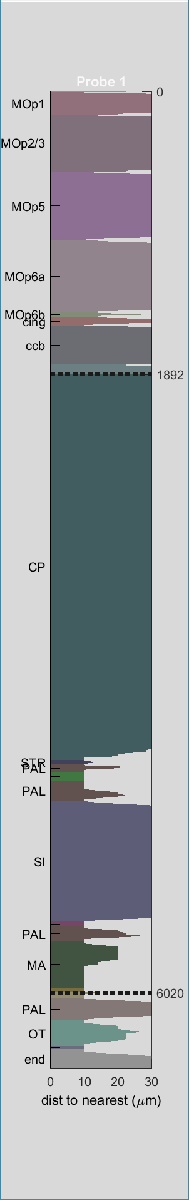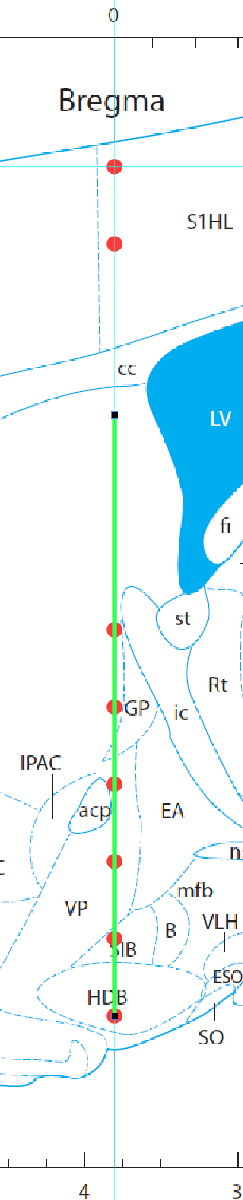

struct_probes = preallocatestruct(...
    {'probe_id', 'probe_AB', 'session_id', 'subject_id', 'probe_note', 'upward_from_tip_um'},...
    size(probes)');

for i = 1:length(probes)
    struct_probes(i).probe_id = i;
    struct_probes(i).probe_AB = '';
    struct_probes(i).session_id = '';
    struct_probes(i).subject_id = subject_id;
    struct_probes(i).probe_note = '';
    struct_probes(i).upward_from_tip_um = 0;
end

% white
struct_probes(1).probe_AB = 'A'; 
struct_probes(1).session_id = 'paxinos'; 


Tprobes = struct2table(struct_probes, 'AsArray',true);
Tprobes.probe_AB = string(Tprobes.probe_AB);
Tprobes.session_id = string(Tprobes.session_id);
Tprobes.subject_id = string(Tprobes.subject_id);

Tprobes

Tprobes = 1×6 table
    probe_id    probe_AB    session_id        subject_id        probe_note    upward_from_tip_um
    ________    ________    __________    __________________    __________    __________________
       1          "A"       "paxinos"     "Paxinos_sagittal"    {0×0 char}            0         

Tapdvml_contacts = vertcat(c_Tapdvml_contacts{:})

Tapdvml_contacts = 384×11 table
      ap_mm       dv_mm     dv_mm_paxinos    ml_mm    annotation             name             acronym    contact_id    probe_id    depth_mm    depth_mm_paxinos
    __________    ______    _____________    _____    __________    ______________________    _______    __________    ________    ________    ________________
         -0.01      7.04       5.6498        -1.41       578        {'Olfactory tubercle'}    {'OT' }         1           1         6.2393          5.7472     
         -0.01      7.04       5.6498        -1.41       578        {'Olfactory tubercle'}    {'OT' }         2   

T_borders = [];
for i = 1:length(probes)
    borders_table{i}.probe_id = repmat(i,height(borders_table{i}),1);
    T_borders = [T_borders; join(borders_table{i}, Tprobes(i,:))];
end

i = T_borders.Properties.VariableNames == "upperBorder";
T_borders.Properties.VariableNames{i} = 'upperBorder_um';

i = T_borders.Properties.VariableNames == "lowerBorder";
T_borders.Properties.VariableNames{i} = 'lowerBorder_um';


accf2pxs_mm(3.2031)

ans = 1.9514

function Tapdvml = apdvml2info(apdvml_points, bregma, atlas_resolution, av, st)
% apdvml_points has three columns for ap, dv, and ml


% see also
% Analyze_Clicked_Points.m

    ap = -(apdvml_points(:,1)-bregma(1))*atlas_resolution;
    dv = (apdvml_points(:,2)-bregma(2))*atlas_resolution;
    ml = (apdvml_points(:,3)-bregma(3))*atlas_resolution;

    % roi_location_curr = [ap dv ml];

    % initialize array of region annotations
    roi_annotation_curr = cell(size(apdvml_points,1),3);  

    % loop through every point to get ROI locations and region annotations
    for point = 1:size(apdvml_points,1)

        % find the annotation, name, and acronym of the current ROI pixel
        ann = av(ceil(apdvml_points(point,1)), ...
            ceil(apdvml_points(point,2)), ...
            ceil(apdvml_points(point,3))); %TODO
        name = st.safe_name{ann};
        acr = st.acronym{ann};

        roi_annotation_curr{point,1} = ann;
        roi_annotation_curr{point,2} = name;
        roi_annotation_curr{point,3} = acr;

    end

    Tapdvml = [table(ap, dv, accf2pxs_mm(dv), ml, 'VariableNames',{'ap_mm','dv_mm', 'dv_mm_paxinos', 'ml_mm'}), ...
        cell2table(roi_annotation_curr, 'VariableNames', {'annotation', 'name', 'acronym'})];

end


function y = accf2pxs_mm(x)

if size(x,2) ==1 
    y = 0.921 * x - 0.834; % global
    % y = 0.908 * x - 0.957; % local

elseif size(x,2) == 3
    % assume that the 2nd column is the DV
    y = x;
    y(:,2) = 0.921 * x(:,2) - 0.834; % global
    % y(:,2) = 0.908 * x(:,2) - 0.957;  % local

else
    error('unexpected size')
end

end
